clear all
warning('off','all')

rasta=20;
rast = 1:rasta;
[X,Y] = meshgrid(rast,rast);
points = [X(:)';Y(:)']; 

objects={}


objects =

  0×0 empty cell array



epsilon=0.0001

epsilon = 1.0000e-04

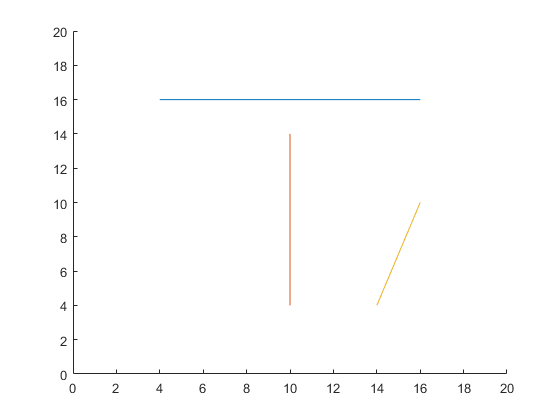

obj1.p1 = [0.2;0.8]*rasta+epsilon;
obj1.p2 = [0.8;0.8]*rasta+epsilon;
obj2.p1 = [0.5;0.7]*rasta+epsilon;
obj2.p2 = [0.5;0.2]*rasta+epsilon;
obj3.p1 = [0.7;0.2]*rasta+epsilon;
obj3.p2 = [0.8;0.5]*rasta+epsilon;

objects{1}=obj1;
objects{2}=obj2;
objects{3}=obj3;

 
figure;
axis([0 rasta 0 rasta])
hold on
for pp=1:size(objects,2)
plot([objects{pp}.p1(1) objects{pp}.p2(1)], [objects{pp}.p1(2) objects{pp}.p2(2)])
end
hold off;


% ------------------------parameters------------------------------

par.h=(rasta/2)^2;
par.price = 50;   %price per lamp
par.powercost = 100   %price per unit of power per year

par = struct with fields:
            h: 100
        price: 50
    powercost: 100


par.targetlum=1;    %
W = 0;             %weight of the financial cost

Maxlamps = 10;
MaxGen = 100;
PopSize = 40;
Mutrate= 0.1;
finalrate=0.01;

minpower = 0.1;
maxpower = 2;
mincoord=0;
maxcoord=rasta;

nvars=3;

xcoord = mincoord+rand()*(maxcoord-mincoord);
ycoord = mincoord+rand()*(maxcoord-mincoord);
powerlevels = minpower+rand()*(maxpower-minpower);

xinit = [xcoord; ycoord; powerlevels]

xinit =    16.7561
   14.7814
    1.9129



f = @(chrom)simplefunc(chrom, objects, points, par, W);

[xxx,fval,exitflag,output] = fmincon(f,xinit,[],[],[],[],[mincoord mincoord minpower],[maxcoord maxcoord maxpower])


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


xxx =     9.6020
    3.0713
    1.5126


fval = 192.7775

exitflag = 2

output = struct with fields:
         iterations: 38
          funcCount: 310
    constrviolation: 0
           stepsize: 2.0123e-10
          algorithm: 'interior-point'
      firstorderopt: 1.8199e+07
       cgiterations: 110
            message: '↵Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.↵↵'


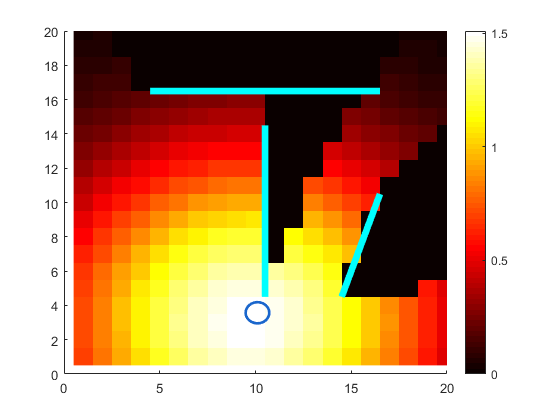


L=xxx;
chrom= [xxx ;1];
[fitness lum] = plotfunc(chrom, objects, points, par, W);
figure;


LIGHT = reshape(lum,[length(rast) length(rast)]);

figure;
hold on
% plot light
axis([0 rasta 0 rasta])
colormap('hot');             
imagesc(LIGHT);
colorbar;
% plot walls
for pp=1:size(objects,2)
pl0t =plot([objects{pp}.p1(1)+0.5 objects{pp}.p2(1)+0.5], [objects{pp}.p1(2)+0.5 objects{pp}.p2(2)+0.5]);
pl0t.LineWidth = 5;
pl0t.Color = 'cyan';
end
% plot lamps
for l=1:size(L,2)
viscircles([L(1,l)+0.5 L(2,l)+0.5],sqrt(L(3,l))/2,'Color',[0.1 0.4 0.8]);
end
hold off

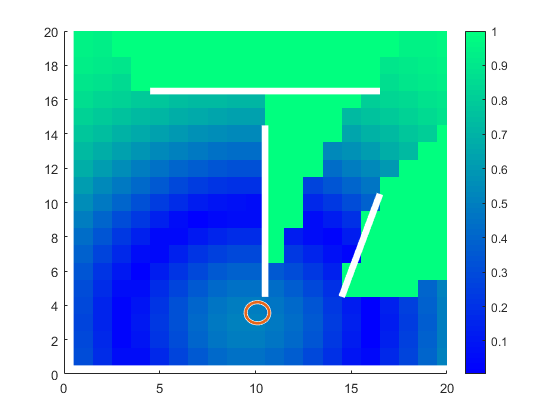


MAP = reshape(abs(lum-par.targetlum),[length(rast) length(rast)]);

figure;
hold on
% plot light
axis([0 rasta 0 rasta])
colormap('winter');             
imagesc(MAP);
colorbar;
% plot walls
for pp=1:size(objects,2)
pl0t =plot([objects{pp}.p1(1)+0.5 objects{pp}.p2(1)+0.5], [objects{pp}.p1(2)+0.5 objects{pp}.p2(2)+0.5]);
pl0t.LineWidth = 5;
pl0t.Color = 'white';
end
% plot lamps
for l=1:size(L,2)
viscircles([L(1,l)+0.5 L(2,l)+0.5],sqrt(L(3,l))/2,'Color',[0.9 0.4 0.1]);
end
hold off